clear
%DidgeridooStudie
%randomisierte klinische Studie zur Messung der Wirksamkeit von
%Didgeridoo-Spielen bei mäßiger Schlafapnoe
%Tagesschläfrigkeit gemessen am Epworth-Index (0-24, 0 keine Tagesschläfrigkeit,
%>11 große Tagesschläfrigkeit)
%Rohdaten (erraten aus den Graphen mit passendem Mittelwert und Standardabweichung)
k1=[23.4 21.5 13.3 11.5 11.2 11.2 10.5 10.5 6.2 5.2 1.2];
k2=[18.5 21.6 9.2 10.6 10.3 6.2 14.5 8.2 5.2 4.2 1.2];
xk=k2-k1;
xk=xk';
d1=[19.2 18.2 15.5 12.5 12.5 12.5 12.5 11.2 11.2 10.2 9.4 9.4 9.3 7.2];
d2=[9.2 8.2 8.2 11.2 8.2 3.2 9.2 5.2 9.2 3.2 9.2 7.4 8.3 6.3];
xd=d2-d1;
xd=xd';
%xd=[-11 -10.45, -8 -1.5 -2.5 -2.5 -5.7 -2 -5.5 -7.5 1.2 -2.8 -1 -2.8]';
k=zeros(length(xk),1);
d=ones(length(xd),1);
x(:,1)=[xk;xd];
x(:,2)=[k;d];

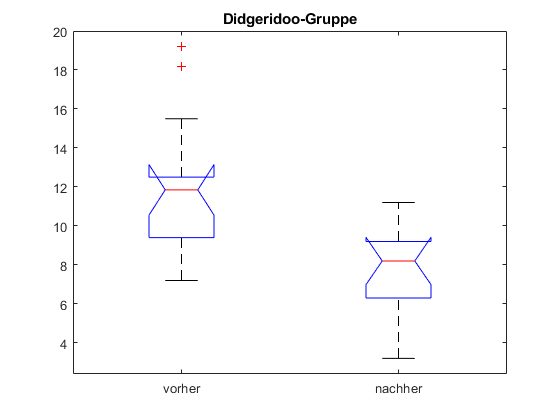

%Didgeridoo-Gruppe
boxplot([d1',d2'],"Notch","on","Labels",{'vorher', 'nachher'})
title("Didgeridoo-Gruppe")

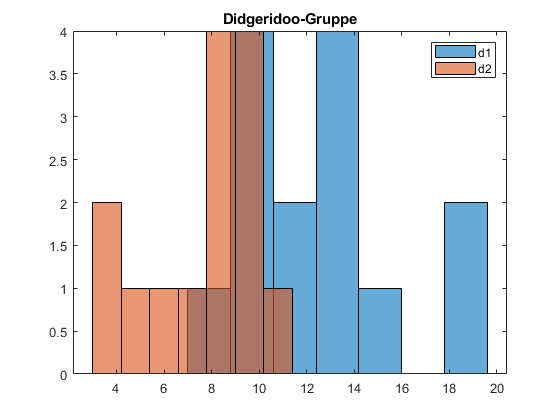

histogram(d1,round(2*sqrt(length(d1)),0))
title("Didgeridoo-Gruppe")
hold on
histogram(d2,round(2*sqrt(length(d2)),0))
legend  
hold off

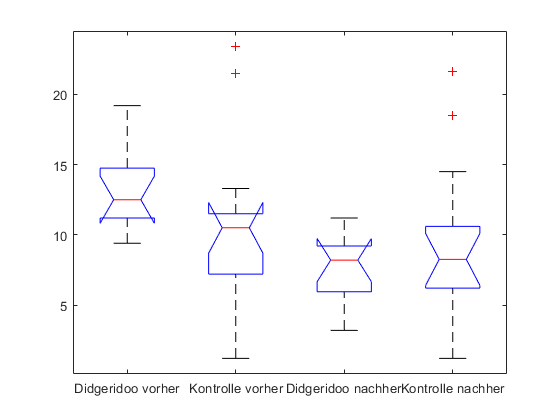

%plus Kontrollgruppe
figure(4)
boxplot([d1';k1';d2';k2'],[x(:,2);x(:,2)+2],"Notch","on",'Labels',{'Didgeridoo vorher', 'Kontrolle vorher','Didgeridoo nachher', 'Kontrolle nachher'})

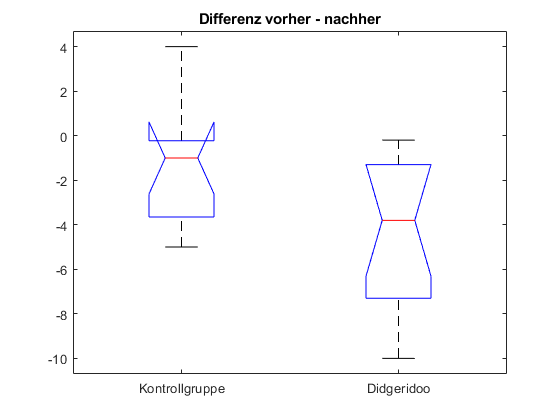

%Charakterisierung der Stichproben:

%Darstellung Boxplot mit Konfidenzintervall zum Median
boxplot(x(:,1),x(:,2),'Notch','on','Labels',{'Kontrollgruppe','Didgeridoo'})
title("Differenz vorher - nachher")


%Didgeridoo-Gruppe
x_d=mean(xd)

x_d = -4.6143

s_d=std(xd)

s_d = 3.5908

SE_d=std(xd)/sqrt(length(xd))

SE_d = 0.9597

%95%-Konfidenzintervall mit t-Verteilung
[~,~,ci_d,~]=ttest(xd)

ci_d =    -6.6875
   -2.5410




%Kontrollgruppe
x_k=mean(xk)

x_k = -1.4545

s_k=std(xk)

s_k = 2.5974

SE_k=std(xk)/sqrt(length(xk))

SE_k = 0.7832

%95%-Konfidenzintervall mit t-Verteilung
[~,~,ci_k,~]=ttest(xk)

ci_k =    -3.1995
    0.2904


%Betrachtung der Differenz zwischen Kontrollegruppe und Didgeridoo-Gruppe

x_diff=x_d-x_k

x_diff = -3.1597

%95% Konfidenzintervall mit Normalverteilung (händisch berechnet)
SE_diff_norm=sqrt(var(xd)+var(xk))/sqrt(length(xk)+length(xd)-2)

SE_diff_norm = 0.9241

SE_diff_norm_ci=[x_diff-1.96*SE_diff_norm x_diff+1.96*SE_diff_norm]

SE_diff_norm_ci =    -4.9709   -1.3485


%Varianz der Grundgesamtheit unbekannt, Stichprobe klein -> t-Verteilung
[~,~,ci_k,~]=ttest2(xd,xk)

ci_k =    -5.8244
   -0.4951


%t-Test
[h0_ttest,p_ttest,ci_ttest,stats_ttest]=ttest2(xd,xk)

h0_ttest = 1

p_ttest = 0.0222

ci_ttest =    -5.8244
   -0.4951


stats_ttest = struct with fields:
    tstat: -2.4530
       df: 23
       sd: 3.1970


%1: h0 ablehnen, 0: h0 nicht ablehnen = beibehalten

%verteilungsfreien Test auf Median:
[h0_rank,p_rank,stats_rank]=ranksum(xd,xk)

h0_rank = 0.0283

p_rank = logical
   1


stats_rank = struct with fields:
       zval: -2.1927
    ranksum: 141.5000
